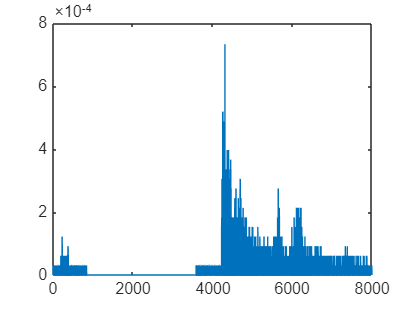

clc;clear;
[y,Fs]=audioread('dspx1.wav');
t = (0:length(y)-1) / Fs; % 计算时间轴
N = length(y); 
f = (0:N-1)*Fs/N;
Y = fft(y); 
X=circshift(Y,2000);
x=ifft(X);
sound(abs(x),Fs);
plot(f, abs(x));
xlim([0,8000]);